## Taller 8.

clc
clear
%Información

k_400 = 1; %min-1
CpA = 40 ; %cal/molK
CpB = CpA ; %Cal/molK1
Keq_400 = 100 ;
V = 10 ; % L
FA0 = 10 ; % mol/min
E_R = 20000 ; % K
UA = 3600 ; % cal/minK
DHr = -80000 ; % cal/mol
Q0 = 1 ; %L/min
T0 = 37 + 273.15 ; %K
Ta = 37 + 273.15 ; %K

#### A. Encuentre una expresión o conjunto de expresiones para calcular G(T).

Realizamos el balance de energía


$$Q-W_s+\sum_iF_{i,in}H_{i,in}-\sum_iF_{i,out}H_{i,out} = 0$$


Que se puede reescribir a


$$Q=\sum_iF_{i,in}(H_{i,out}-H_{i,in})+V \sum_j R_j \Delta H_{r,j (T_{in})}$$


En este caso tenemos una reacción sencilla


$$A \longleftrightarrow B$$


Por tanto,


$$\sum_j R_j \Delta H_{r(T_{in})} = R_1 H_{r1}$$


Que se puede expresar en términos de la conversión de la siguiente forma


$$F_{A,in} - F_{A,out} + (-R_1)V =0 \rightarrow R_1V = F_{A,in}x_A$$



$$\rightarrow V \sum_j R_j \Delta H_{r,j (T_{in})} = F_{A,in}x_AH_{r1}$$


Por otro lado, para procesos isobáricos se expresa el cambio de entalpía como


$$H_{i,out}-H_{i,in} = \int_{T_{in}}^{T_{out}} Cp_i dT$$


Que si se trabaja con una capacidad calorífica promedio, se puede aproximar a


$$H_{i,out}-H_{i,in} = \bar{Cp}_i ( T_{out}-T_{in} )$$


Reescribiendo el balance de energía a


$$Q=F_{A,in}\bar{Cp}_A ( T_{out}-T_{in} )+F_{A,in}x_AH_{r1}$$


Ahora, bajo la suposición de que el flujo de fluido de intercambio de calor es lo suficientemente alto como para que su temperatura sea en promedio constante, entonces el calor que suministra la chaqueta se puede expresar como


$$Q=UA(T_a-T)$$


Encontrando la ecuación del balance de energía


$$UA(T_a-T)=F_{A,0}\bar{Cp}_A ( T-T_{0} )+F_{A,0}x_AH_{r1}$$



$$\rightarrow \frac{UA}{F_{A0}\bar{Cp}_{A}}(T_a-T)-(T-T_0)-\frac{x_A \Delta H_{r,(T_0)}}{\bar{Cp}_A}=0$$


Definiendo  $\lambda=\frac{UA}{F_{A0}Cp_{A}}$, entonces


$$\lambda T_a+T_0-T(1+\lambda)= \frac{x_A \Delta H_{r,(T_0)} }{\bar{Cp}_A}$$



$$\bar{Cp}_A(1+\lambda)\left[ \frac{\lambda T_a+T_0}{1+\lambda} -T \right]=x_A \Delta H_{r,(T_0)}$$


Si $T_C=\frac{\lambda T_a+T_0}{1+\lambda}$, se puede reescribir una vez más esta ecuación a


$$\bar{Cp}_A(1+\lambda)(T-T_c)=x_A(-\Delta H_{r,(T_0)})$$


 Donde el término del costado izquierdo corresponde a $R(T)$ y el lado derecho a $G(T)$. Es decir que $G(T)=x_A(-\Delta H_{r,(T_0)})$, realizando el balance molar para la especie $A$


$$F_{A0}-F_A+r_AV=0\rightarrow Q_0C_{A0}x_A+r_AV=0$$


Como es una reacción reversible


$$r_A=-R_1=-k_1C_A+k_{-1}C_B=-k_1 C_{A0}(1-x_A)-k_{-1}C_{A0}x_A$$



$$r_A=-k_1 C_{A0}\left[1-x_A\left(1+\frac{1}{K_c}\right) \right]$$


Reemplazamos en el balance de materia y encontramos


$$Q_0C_{A0}x_A-k_1 C_{A0}\left[1-x_A\left(1+\frac{1}{K_c}\right) \right]V=0$$


Encontrando


$$x_A=\frac{k_1\tau}{1+k_1\tau\left(1+\frac{1}{K_c}\right)$$



$$Donde:$$
 
$$\tau=\frac{V}{Q_0}$$


Además, como


$$\Delta H_{r,(T_0)}=H_r^{ref}+\Delta Cp (T_0-T_{ref})}$$


Y tenemos $Cp_A=Cp_B$ con coeficientes estequiométricos de $-1{$ y $1$, respectivamente, entonces $\Delta Cp=0$, encontrando la siguiente expresión de $G(T)$,


$$G(T)=\frac{k_1\tau (-\Delta H_r)}{1+k_1\tau\left(1+\frac{1}{K_c}\right)$$


#### B. Cuáles son las temperaturas de estado estacionario?

Calculamos las funciones de $R(T)$ y $G(T)$,

% Calculots R(T)
lambda = @(UA) UA/FA0/CpA;
Tc = @(UA,Ta) (lambda(UA)*Ta+T0)./(1+lambda(UA)) ;
R = @(T,UA,Ta) CpA*(1+lambda(UA)).*(T-Tc(UA,Ta)) ;

% Calculos G(T)
Rgi = 1.987207 ; %cal/molK
k1 = @(T) k_400*exp(-E_R*(1./T-1./400)) ;
Kc = @(T) Keq_400*exp(-DHr/Rgi*(1./T-1./400)) ;
tao = V/Q0 ; %min
xA = @(T) k1(T).*tao./(1+k1(T).*tao.*(1+1./Kc(T)))

xA = function_handle with value:
    @(T)k1(T).*tao./(1+k1(T).*tao.*(1+1./Kc(T)))



G = @(T) xA(T)*-DHr;


Y graficamos las curvas de $R$ y $G$

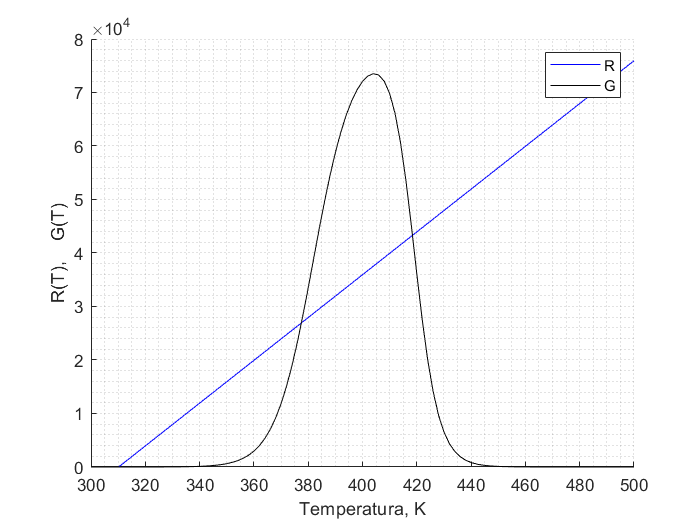

figure('Color','white')
T = linspace(300,500,101) ;
hold on
plot(T,R(T,UA,Ta),'b')
plot(T,G(T),'k')
xlabel('Temperatura, K')
ylabel('R(T),    G(T)')
legend('R','G')
grid minor
ylim([0,8e4])

Las temperaturas de estado estacionario son los puntos de intercepción de estas dos curvas, es decir,

options = optimoptions('fsolve','Display','none');
Te1 = fsolve(@(T) R(T,UA,Ta)-G(T),300,options)

Te1 = 310.1510

Te2 = fsolve(@(T) R(T,UA,Ta)-G(T),380,options)

Te2 = 377.4979

Te3 = fsolve(@(T) R(T,UA,Ta)-G(T),420,options)

Te3 = 418.4024

#### D. Cuál es la conversión que corresponde al estado estacionario superior?

xAsup = xA(Te3)

xAsup = 0.5413

#### E. Varíe la temperatura ambiente, $T_a$, y construya una gráfica de la temperatura del reactor, $T$ ,  en función de $T_a$, identificando las temperaturas de ignición y de extención.

Para encontrar los puntos de ignición y extinción se debe cumplir que


$$R(T)=G(T)$$



$$\frac{dR(T)}{dT}=\frac{dG(T)}{dT}$$


Resolvemos el sistema de ecuaciones en los dos puntos, encontramos las siguientes temperaturas de de ignición

syms x
dG = inline(diff(G(x))) ;
dR = inline(diff(R(x,UA,Ta))) ;
X = fsolve(@(X)[dR(UA)-dG(X(1)); R(X(1),UA,X(2))-G(X(1))],[350;350],options) ;
Tai = X(2)

Tai = 357.3100

Y la temperatura de extinción

X = fsolve(@(X)[dR(UA)-dG(X(1)); R(X(1),UA,X(2))-G(X(1))],[410;200],options) ;
Tae = X(2) 

Tae = 209.1571

Y graficamos la solución

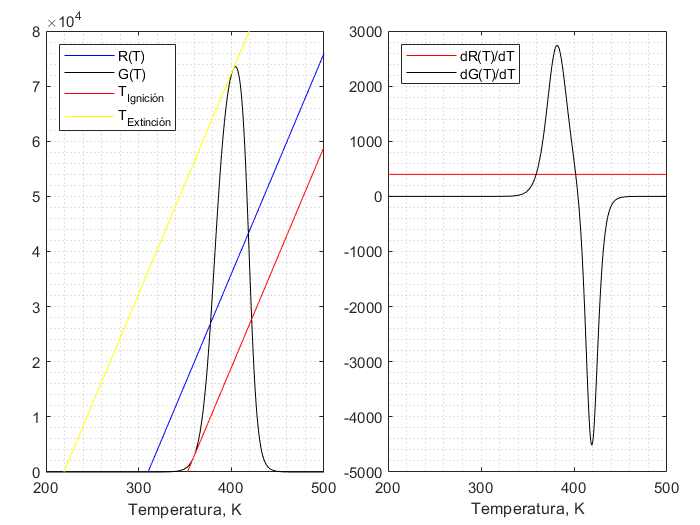

% Gráficas
T = 200:0.5:500 ;
figure('Color','White')
tiledlayout(1,2,'padding','compact','TileSpacing',"compact")
nexttile
plot(T,R(T,UA,T0),'b',T,G(T),'k',T,R(T,UA,Tai),'r',T,R(T,UA,Tae),'y')
legend('R(T)','G(T)','T_{Ignición}','T_{Extinción}','Location','NorthWest')
xlabel('Temperatura, K')
ylim([0 8e4])
grid minor

nexttile
plot(T,dR(T)*ones(size(T)),'r',T,dG(T),'k')
legend('dR(T)/dT','dG(T)/dT','Location','NorthWest')
xlabel('Temperatura, K')
grid minor

Una vez identificadas las temperaturas de ignición y extinción, se determina el intervalo de temperatura donde se tendrán los 3 estados estacionarios y se calculan las intersecciones entre $R(T)$ y $G(T)$ superior e inferior con los cuales realizar la curva $T$ vs $T_a$.

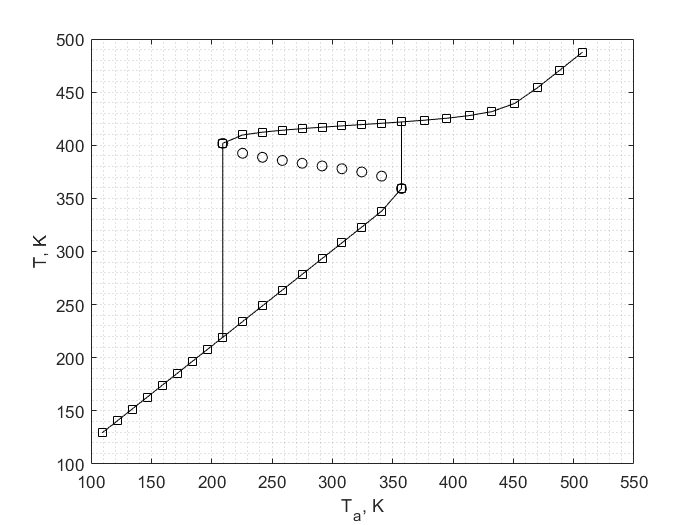

Tag1 = linspace(Tae-100,Tae,9)' ;
Tag2 = linspace(Tae,Tai,10)' ;
Tag3 = linspace(Tai,Tai+150,9)' ;

% Sección antes de la temperatura Ta de extinción
for i = 1:size(Tag1,1)
Te11(i,1) = fsolve(@(T) R(T,UA,Tag1(i))-G(T),300,options) ;
end

% Sección entre la temperatura de extinción e ignición
for i = 1:size(Tag2,1)
Te12(i,1) = fsolve(@(T) R(T,UA,Tag2(i))-G(T),300,options) ; 
Te2(i,1) = fsolve(@(T) R(T,UA,Tag2(i))-G(T),380,options) ;
Te32(i,1) = fsolve(@(T) R(T,UA,Tag2(i))-G(T),420,options) ;
end

% Sección después de la temperatura Ta de ignición
for i = 1:size(Tag3,1)
Te31(i,1) = fsolve(@(T) R(T,UA,Tag3(i))-G(T),420,options) ;
end

% Organizamos los resultados para que queden en un mismo vector
Te1 = [Te11;Te12;Te31] ;
Te3 = [Te11;Te32;Te31] ;
Tagraf = [Tag1;Tag2;Tag3] ;

% Graficamos
figure('Color','white')
plot(Tagraf,Te1,'ks-',Tagraf,Te3,'ks-',Tag2,Te2,'ok')
xlabel 'T_a, K'
ylabel 'T, K'
grid minor

#### G. Qué valor del producto UA dará la conversión máxima?

El producto $UA$ es proporcional a $G(T)$, es decir que maximizando $G(T)$ se obtiene $UA_{max}$

% UAmax
[Gmax, indmax] = max(G(T)) ;
Tmax = T(indmax) ;
UAmax = fsolve(@(UA) R(Tmax, UA,Ta)-G(Tmax),UA,options)

UAmax = 7.3934e+03